## **Equações de montagem dos modelos ligado e desligado do MOSFET :**

    Cmed: Matriz de espaço de estado que seleciona a saída desejada na matriz de variaveis de estado, no nosso caso a polaridade é invertida em função da troca do comportamento do indutor, então optamos por -1 na seleção da variável.

syms R L C D V0 IL s Vin
%EQUACOES MONTAGEM DO MODELO MÈDIO:---------------------------------------------
I = eye(2);

Aon  = [(-1/(R*C)) 0 ; 0 0]
Aoff = [(-1/(R*C)) (1/C);(-1/L)  0]


Bon= [0 ; 1/L]
Boff=[0;0]


Cmed = [-1 0]
Dmat = 0

## **Montagem do modelo médio das equações de espaço de estado :**

    Pelo sistema possuri dois estados, a linearização destes estados levando em conta o duty cicle fixo e os componentes ativos com comportamento ideal pode ser descrito como a construção do modelo médio de duração de cada uma das fases dessa dinâmica, para o MOSFET ligado (D) e para o mesfet desligado (1-D).

Amed = (Aon*D) + (Aoff*(1-D));
Amed = simplify(Amed)

$$Amed = \left(\begin{array}{cc} -\frac{1}{C\,R} & -\frac{\text{D}-1}{C}\\ \frac{\text{D}-1}{L} & 0 \end{array}\right)$$


Bmed= (Bon*D) + (Boff*(1-D))

$$Bmed = \left(\begin{array}{c} 0\\ \frac{\text{D}}{L} \end{array}\right)$$

## **Substituição das varíáveis no espaço de estado para obtenção dos resultados :**

    Neste bloco realizo a montagem do espaço de estados completo, em seguido aplico uma entrada degral*24 referente ao nosso Vin para confirmação.

Amed_num = Amed;
Amed_num = subs(Amed_num,[R, L, C, D], [4 , 20e-6 , 80e-6 , 0.4])

$$Amed\_num = \left(\begin{array}{cc} -3125 & 7500\\ -30000 & 0 \end{array}\right)$$


Bmed_num = Bmed;
Bmed_num = subs(Bmed_num,[R, L, C, D], [4 , 20e-6 , 80e-6 , 0.4])

$$Bmed\_num = \left(\begin{array}{c} 0\\ 20000 \end{array}\right)$$


Amed_num=double(Amed_num);
Bmed_num=double(Bmed_num);

espaco_de_estado = ss(Amed_num , Bmed_num , Cmed , Dmat)

espaco_de_estado =
 
  A = 
           x1      x2
   x1   -3125    7500
   x2  -3e+04       0
 
  B = 
          u1
   x1      0
   x2  2e+04
 
  C = 
       x1  x2
   y1  -1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



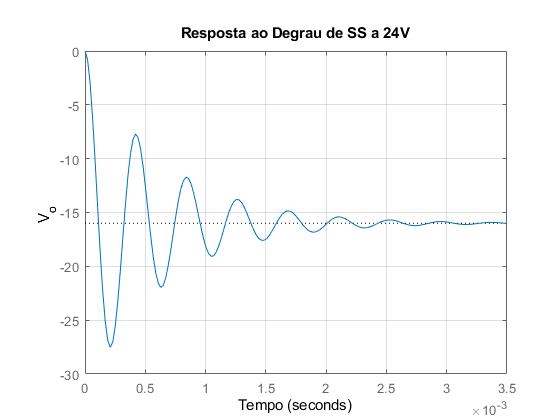


stepplot(espaco_de_estado * 24);
title('Resposta ao Degrau de SS a 24V')
xlabel('Tempo')
ylabel('V_o')
grid on


%step(24*espaco_de_estado)
pole(espaco_de_estado)

ans = 	1.0e+04 *

  -0.1563 + 1.4918i
  -0.1563 - 1.4918i


## **Construindo a função de trasferência a partir da equação conhecida :**

    Construimos então a função de trasferência a partir da equação $G\left(s\right)\;=\;C*{\left(s*I-A\right)}^{-1} *\left(B+D\right)$ e vemos que ela bate com o step aplicado diretamente na SS do item anterior, garantinod que esta é equivalente.

%BLOCO ONDE USO O MODELO DE CONVERSAO CLASSICO (Vo/Vin)
Gs = Cmed*(inv(s * I - Amed_num))*(Bmed_num + Dmat);
Gs = simplify(Gs)

$$Gs = -\frac{150000000}{s^{2}+3125\,s+225000000}$$

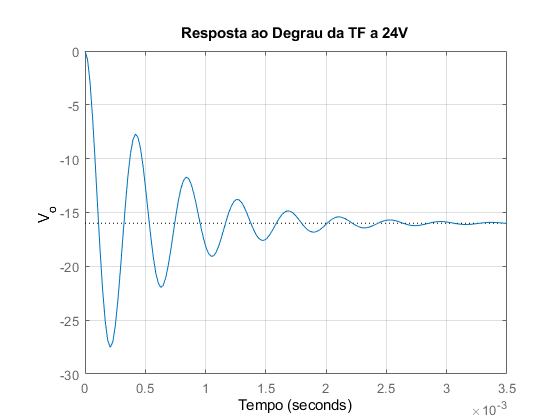


[num, den] = numden(Gs);
num = sym2poly(num);
den = sym2poly(den);

Gstf = tf(num,den);

a1 = 24;
%PLOTANDO A FIGURA PARA ENTRADA DE 24V (1*24)
stepplot(Gstf * a1);
title('Resposta ao Degrau da TF a 24V')
xlabel('Tempo')
ylabel('V_o')
grid on


ganho = dcgain(Gstf);
pole(Gstf);
%RESPOSTA IGUAL A ANTERIOR DO SS, OK


## **Obtenção de informações do sistema com o matlab :**

    As características do sistema podem ser determinadas a partir de cáclculos com as componentes da função de transferência ou análise visual do gráfico, aqui optamos por funções que retornam mais precisamente o resultado destas análises, como o stepinfo, com a entrada de 24V referente, que pode ser aplicado tanto no espaço de estado quando na função de trasnferência.

[infov, infot] = step(Gstf*a1);
info = stepinfo(Gstf*a1)

info = struct with fields:
        RiseTime: 7.5398e-05
    SettlingTime: 0.0024
     SettlingMin: -27.5121
     SettlingMax: -7.7194
       Overshoot: 71.9508
      Undershoot: 0
            Peak: 27.5121
        PeakTime: 2.0944e-04


valor_final = infov(end)

valor_final = -15.9173

    Vemos aqui a necessidade de controlar o modelo pois ele, em malha aberta, não atinge as especificações de projeto.

    Este modelo que leva  em consideração Vo/Vi é útil para avaliar o comportamento do sistema, porém, quando queremos controla-lo, devemos levar em consideração o Duty Cicle como variável de controle, que é o atuador PWM controlável para ajuste da saída, e não a tensão de entrada que não pode ser facilemnte manipulada.

## **Para implementações de funções de trasnferências baseadas no Duty Cicle como variável manipulável :**

    Já que para controlar o circuito, precisamos da função de trasnferência em função da variável manipulável, o Duty Cicle do MOSFET que caracteriza o PWM do circuito é o melhor candidato, fazemos o modelo de pequeno sinal ao redor do Duty Cicle para obter Vo/D como TF, utilizando a modelagem padrão do modelo de conversor Buck Bosster, $G\left(s\right)\;=\;C*{\left(s*I-A\right)}^{-1} *B_d$, sedo $B_d =\left(A_{\mathrm{on}} -A_{\mathrm{off}} \right)*X_{\mathrm{med}} +\left(B_{\mathrm{on}} {-B}_{\mathrm{off}} \right)*U_{\mathrm{med}}$ e $X_{\mathrm{med}}$ a manipulação das variáveis de estado em torno do modelo de pequeno sinal do circuito definida por $X_{\mathrm{med}} ={\left(-A_{\mathrm{med}} \right)}^{-1} *B_{\mathrm{med}} *V_{\mathrm{in}}$.

    Assim consideramos que a nossa variável de controle será equivalente a pequenas variações em torno do ponto de operação do Duty Cicle "$d\left(t\right)$" para que consigamos nos manter na área linear do ganho em função da razão cíclica aplicaremos:

Xmed = inv(-Amed)*Bmed*Vin

$$Xmed = \left(\begin{array}{c} -\frac{\text{D}\,\mathrm{Vin}}{\text{D}-1}\\ \frac{\text{D}\,\mathrm{Vin}}{R\,{\left(\text{D}-1\right)}^{2}} \end{array}\right)$$

Bd = (Aon-Aoff)*Xmed + (Bon-Boff)*Vin

$$Bd = \left(\begin{array}{c} -\frac{\text{D}\,\mathrm{Vin}}{C\,R\,{\left(\text{D}-1\right)}^{2}}\\ \frac{\mathrm{Vin}}{L}-\frac{\text{D}\,\mathrm{Vin}}{L\,\left(\text{D}-1\right)} \end{array}\right)$$

    Assim fazemos a função de trasnferência de pequnas variações de X(s) / pequenas variações de D(s) como a seguinte equação desenvolvida a partir do modelo de pequeno sinal, logo em seguida escolhendo a componente de X(s) (Variavel de estado), que queremos a função de tranferência

Gxds = inv(s*I-Amed) * Bd

$$Gxds = \begin{array}{l} \left(\begin{array}{c} -\frac{L\,R\,\sigma_{2}\,\left(\text{D}-1\right)}{\sigma_{1}}-\frac{\text{D}\,L\,\mathrm{Vin}\,s}{{\left(\text{D}-1\right)}^{2}\,\sigma_{1}}\\ \frac{L\,\sigma_{2}\,\left(C\,R\,s+1\right)}{\sigma_{1}}-\frac{\text{D}\,\mathrm{Vin}}{\left(\text{D}-1\right)\,\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=R\,{\text{D}}^{2}-2\,R\,\text{D}+C\,L\,R\,s^{2}+L\,s+R\\ \sigma_{2}=\frac{\mathrm{Vin}}{L}-\frac{\text{D}\,\mathrm{Vin}}{L\,\left(\text{D}-1\right)} \end{array}$$


%A PRIMEIRA LINHA É deltaV0(s)/deltaD(s) que é o que queremos, e a segunda é deltaIL(s)/deltaD(s)
Gxds = simplify(Gxds(1))

$$Gxds = \frac{\mathrm{Vin}\,\left(R+{\text{D}}^{2}\,R-2\,\text{D}\,R-\text{D}\,L\,s\right)}{{\left(\text{D}-1\right)}^{2}\,\left(R\,{\text{D}}^{2}-2\,R\,\text{D}+C\,L\,R\,s^{2}+L\,s+R\right)}$$

     Aplicando o ponto de operação fornecido podemos analisar:

%ESSA PLANTA SÓ MOSTRA A VARIAÇÂO DE Vo, SENDO NECESSARIO SOMAR O Vo
%ESTACIONARIO DE -16 A ESSA VARIAÇÃO PRA CONSEGUIR O VALOR REAL

Gxds = subs(Gxds,[R, L, C, D, Vin], [4, 20e-6 , 80e-6 , 0.4 , 24]);
Gs = simplify(Gxds);
[num, den] = numden(Gs);
numct = -sym2poly(num);
denct = sym2poly(den);
Gtfbuckb = tf(numct,denct)

Gtfbuckb =
 
     250000 s - 4.5e10
  ------------------------
  3 s^2 + 9375 s + 6.75e08
 
Continuous-time transfer function.




a2 = 0.02

a2 = 0.0200

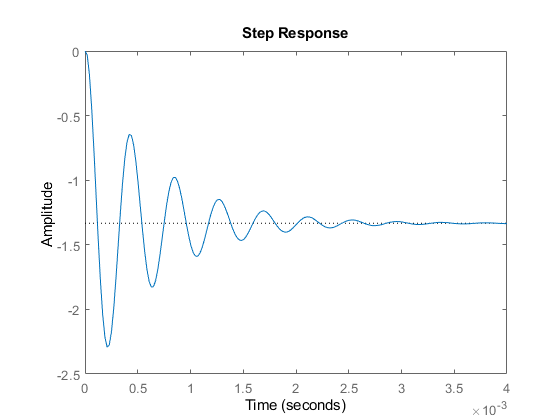

step(Gtfbuckb*a2)

[magnitude, ] = step(Gtfbuckb*a2);

valorfinal = magnitude(end)            %Variação da tensão em torno do ponto de operação

valorfinal = -1.3309

valorfinal + valor_final;              %Valor do sinal após essa variação causada pelo ~d(s)


%CONFIRMAÇÃO DO VALOR DO MODELO DE PEQUENO SINAL deltaVo = ((-Vi)/((1-D)^2))*d 
deltaVo = ((-24)/((1-0.4)^2))*0.02

deltaVo = -1.3333

%O MODELO FUNCIONA COMO ESPERADO COM ERRO BAIXO.

      A função atual em malha fechada com feedback unitário é caracterizada por:

Gtfbuckb_MF = feedback(Gtfbuckb,1)

Gtfbuckb_MF =
 
       250000 s - 4.5e10
  ---------------------------
  3 s^2 + 259375 s - 4.433e10
 
Continuous-time transfer function.



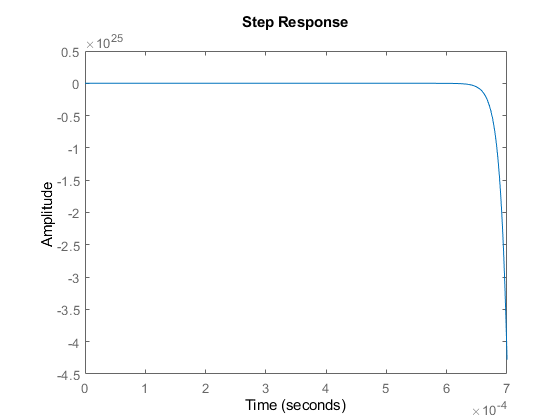

step(Gtfbuckb_MF)

    Com resposta exponencial instável, esperado devido zero localizado no semiplano direito, desenvolvemos então o controlador PI para controle desta malha.

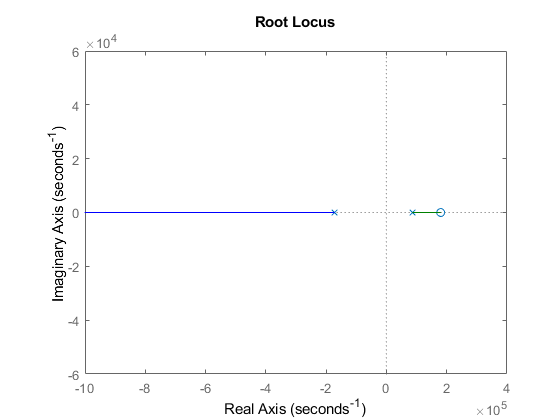

rlocus(Gtfbuckb_MF)

## **Controlador PI obtido através do SISOTOOL :**

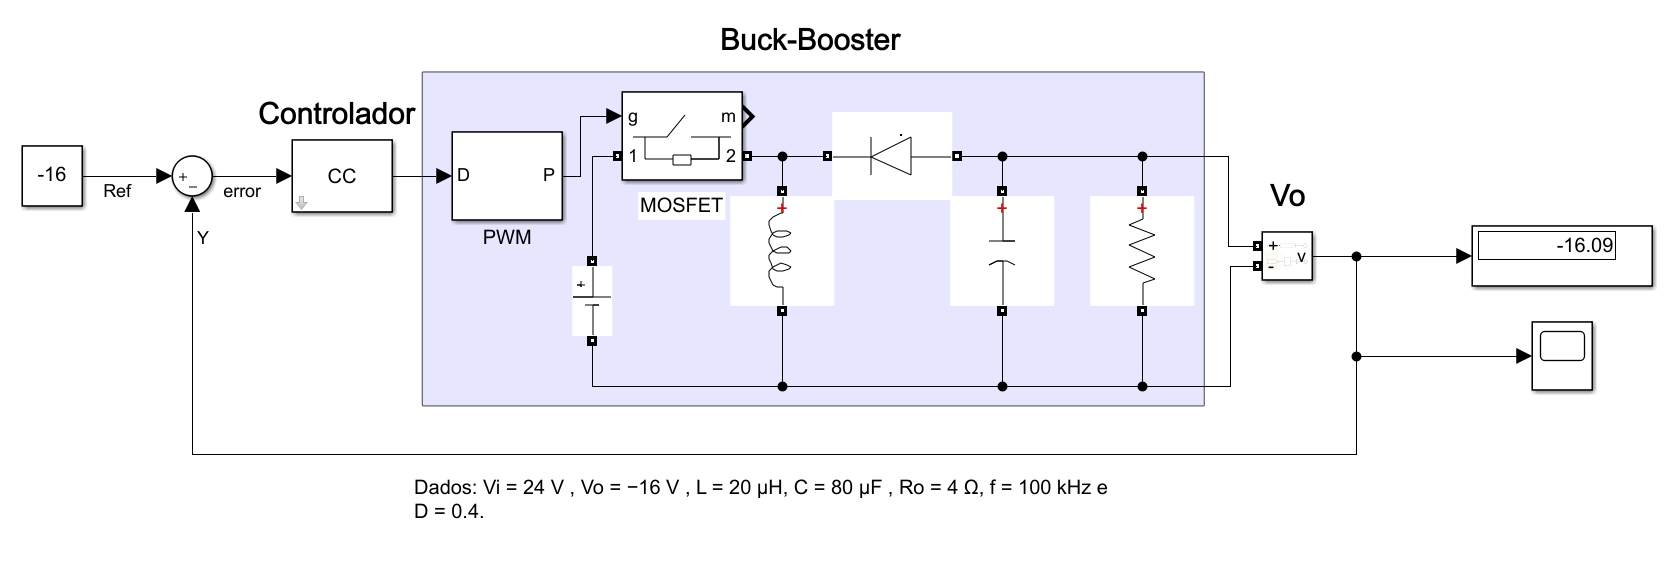

    Optei pelo controlador PI por sua facilidade de implementação e manipulação, a capacidade de implementar integrador para seguir referências e o controle proporcional.

    A imagem anterior mostra o driagrama de blocos do modelo controlado através do controlador PI em feedback unitário, nele o bloco Buck-Booster simulado com o circuito real é resumido pela nossa função de trasnferência "Gtfbuckb".

pole(Gtfbuckb) % Posicionei o zero  do controlador neste polo da função para anular comportamentos indesejados

ans = 	1.0e+04 *

  -0.1563 + 1.4918i
  -0.1563 - 1.4918i


esse = tf('s') %Apelido de 's' para não influenciar no resultado das outras funções

esse =
 
  s
 
Continuous-time transfer function.



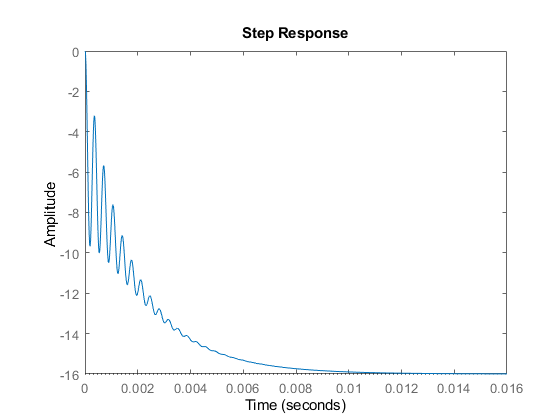

FuncControlador = -0.0063898*(esse+1563)/esse;
%FuncControlador = -0.0038388*(esse+1563)/esse;  para Kp = -6

sistema_controlado = feedback(Gtfbuckb*FuncControlador,1);

step(-16*sistema_controlado)

stepinfo(-16*sistema_controlado)

ans = struct with fields:
        RiseTime: 0.0040
    SettlingTime: 0.0076
     SettlingMin: -15.9975
     SettlingMax: -14.3927
       Overshoot: 0
      Undershoot: 0
            Peak: 15.9975
        PeakTime: 0.0179


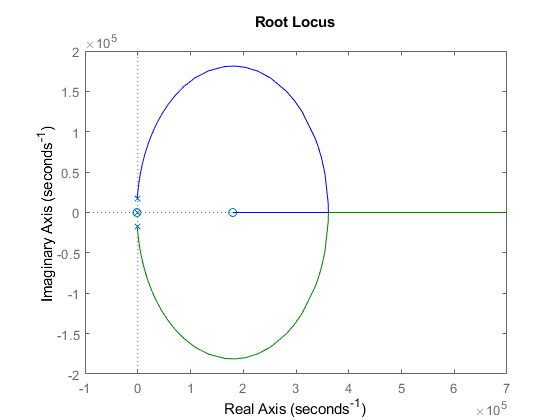



rlocus(sistema_controlado) %lugar das raizes do sistema controlado [NOTA-SE POUCA MARGEM PARA GANHO ESTÁVEL]

    O controlador não consegue cumprir com o requisito de tempo de assentamento menor que 2ms, ficando no valor de 7.6ms, porém

**Gráfico da flutuação ao redor do valor estacionário:**

     Podemos ver através do gráfico resultante aplicado no sistema em feedback unitário com o controlador que a variação dentro do settlingTime é de 15.9 e 16.1, uma variação aceitaval para um conversor CC chaveado na grande maioria das aplicações, atingindo satisfatoriamente o valor de referência de -16V

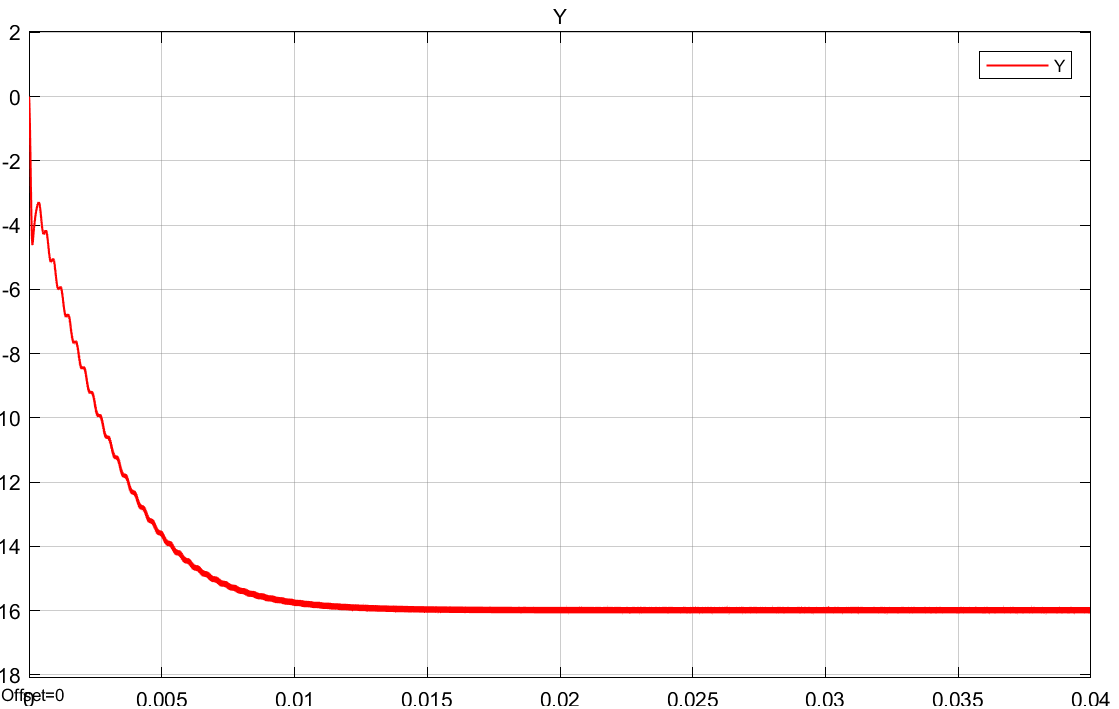

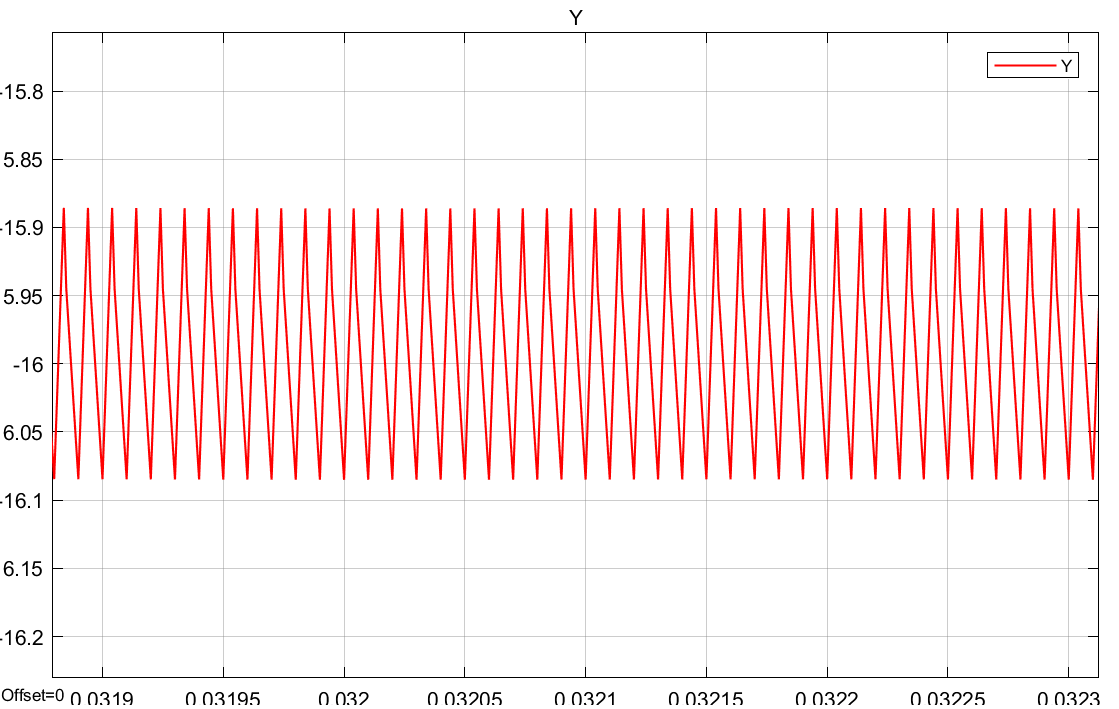

### ANOTAÇÕES EXTRAS E CÓDIGOS COMENTADOS:

%syms kp ki s
%exp = (kp*s + ki)/s
%expo = subs(exp,[kp, ki],[0.005, 6.94])
%[num, den] = numden(expo)
%num = sym2poly(num)
%den = sym2poly(den)
%expo = tf(num,den)

%fb = feedback(Gstf * expo,1)

%rlocus(fb)
%pole(fb)
%zero(fb)

%A PARTIR DAQUI É SO TESTE SOBRE COISAS-----------------------------------------
%p = pole(Gtfbuckb);
%z = zero(Gtfbuckb);

%K_controler = 0.000001;
%z_controler = real(p(1))

%PIC = K_controler*(s + abs(z_controler)/s);
%[num, den] = numden(PIC);
%num = sym2poly(num);
%den = sym2poly(den);
%PIC = tf(num,den)

%GsMaPi = PIC*Gtfbuckb

%rlocus(GsMaPi)

%GsMF = feedback(Gtfbuckb*PIC,1)
%step(GsMF)


%rltool(funcao)
%step ((-1/4)*Gtfbuckb)
%syslin = stepinfo((1/4)*Gtfbuckb)

%INFORMAÇÕES DO SISTEMA---------------------------------------------------------
%[y, t] = step(Gstf*24);
%ymax = max(y);
%yest = y(end)
%OS = ((ymax - yest) / yest) * 100
%ganho = dcgain(Gstf);

%SAÍDA ESPERADA:
%V0esperado = (-D/(1-D)) * Vin
%subs(V0esperado,[D,Vin],[0.4,24])

%ANÁLISE DO GANHO
%step (Gstf)

%COERENTE COM O GANHO ESPERADO V0/Vi = 24/16
%subs (Vin , 24);
%saida = Vin * ganho;
%subs (saida,Vin,24)

%----------------------------------------- ESQUEÇA TODO O RESTO A PARTIR DAQUI APENAS DELIRIOS ------------------------------------------------

%SAÍDA ESPERADA:
%V0esperado = (-D/(1-D)) * Vin
%subs(V0esperado,[D,Vin],[0.4,24])

%----------------------------------------------------------------------------------------------------------
%FEEDBACK E TENTATIVA DE CONTROLE PI:
%Ki = 0.01
%num = [0 1]
%den = [1 0]
%integrador = tf(num, den)
%Kp = 2
%Cnormal = 1 + (1/Kp/Ki)
%Gtfbuckb = feedback(PI * Gtfbuckb)
%rlocusx(Gtfbuckb*integrador)

%----------------------------------------------------------------------------------------------------------
%Bd = (Aon-Aoff)*

%Gsbuckb = C*(sI-A)^-1 *Bd

%Amed = [0 ((D-1)/L) ; ((1-D)/C) (-1/(R*C))];
%Bmed = [(D/L) ; 0];
%Cmed = [1 0];
%Dmed = 0;
%I = [1 0; 0 1];

%Vin é o valor médio da tensão de entrada no conversor CC-CC
%Xmed = inv(-Amed) * Bmed * Vin;
%Amed = (Aon*D) + Aoff*(1-D);


%Gssymb = Cmat* inv((s*I)-Amat) * (Bmat+Dmat)
%Gs = subs(Gssymb,[R, L, C, D], [4,20e-6,80e-6,0.4])
%Gs = simplify(Gs)

%[num den] = numden(Gs)
%num = sym2poly(num)
%den = sym2poly(den)

%Gstf = tf(num,den)

%step (Gstf)



%D = 0.4;
%Vi = 24;
%L = 20e-6;
%C = 80e-6;
%R = 4;
%s = tf('s');


%syms IL(t) Vo(t) Vi D L C R s
%s = tf('s')
%Gs =  (-((D*Vi)/C*R*((1-D)^2))  *  (s-((R*(1-D)^2)/D*L))/(s^2+(1/(R*C)*s)+(((1-D)^2)/(C*L))))

%rlocusx(Gs)


### **TF Construida a mão a partir do vídeo mencionado(Vo/D) para testes:**

%syms Dmed
%Gsmanual = ((Dmed*Vin)/(C*R*(1-Dmed)^2)) * (s-(((R*(1-Dmed)^2)/(Dmed*L))))/(s^2+(1/(C*R))*s + (((1-Dmed)^2)/(C*L)))
%Gsmanual = subs(Gsmanual,[R, L, C, Dmed, Vin], [4,20e-6,80e-6,0.4,24]);
%[num, den] = numden(Gsmanual);
%num = sym2poly(num);
%den = sym2poly(den);
%Gsmanual = tf(num,den);
%step (Gsmanual*0.005, "r")

%O MÉTODO DA SELECAO DA LINHA É IGUAL ESSE, CONFIRMA QUE É SÓ O LA DE CIMA ESCRITO DIFERENTE